# **IO3xx I2C - Loopback**

This example demonstrates the communication between an I2C Master and Slave***,*** which are both on the same I/O module. You can test the basic functionality of I2C Master and I2C Slave by running this loopback test.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **1 x I2C Master channel **and** 1 x I2C Slave channel  **     

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, data is sent from the I2C Master to the I2C Slave and vice versa. You must therefore connect the corresponding pins on the terminal board as indicated in the following pin wiring table. The exact pins depend on the configuration file (bitstream) used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires.

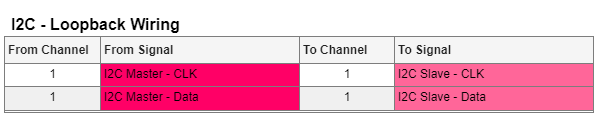

## Initialize and Open the Simulink model

% Open Simulink model
modelName = 'sgMdl_IO3xx_I2C_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

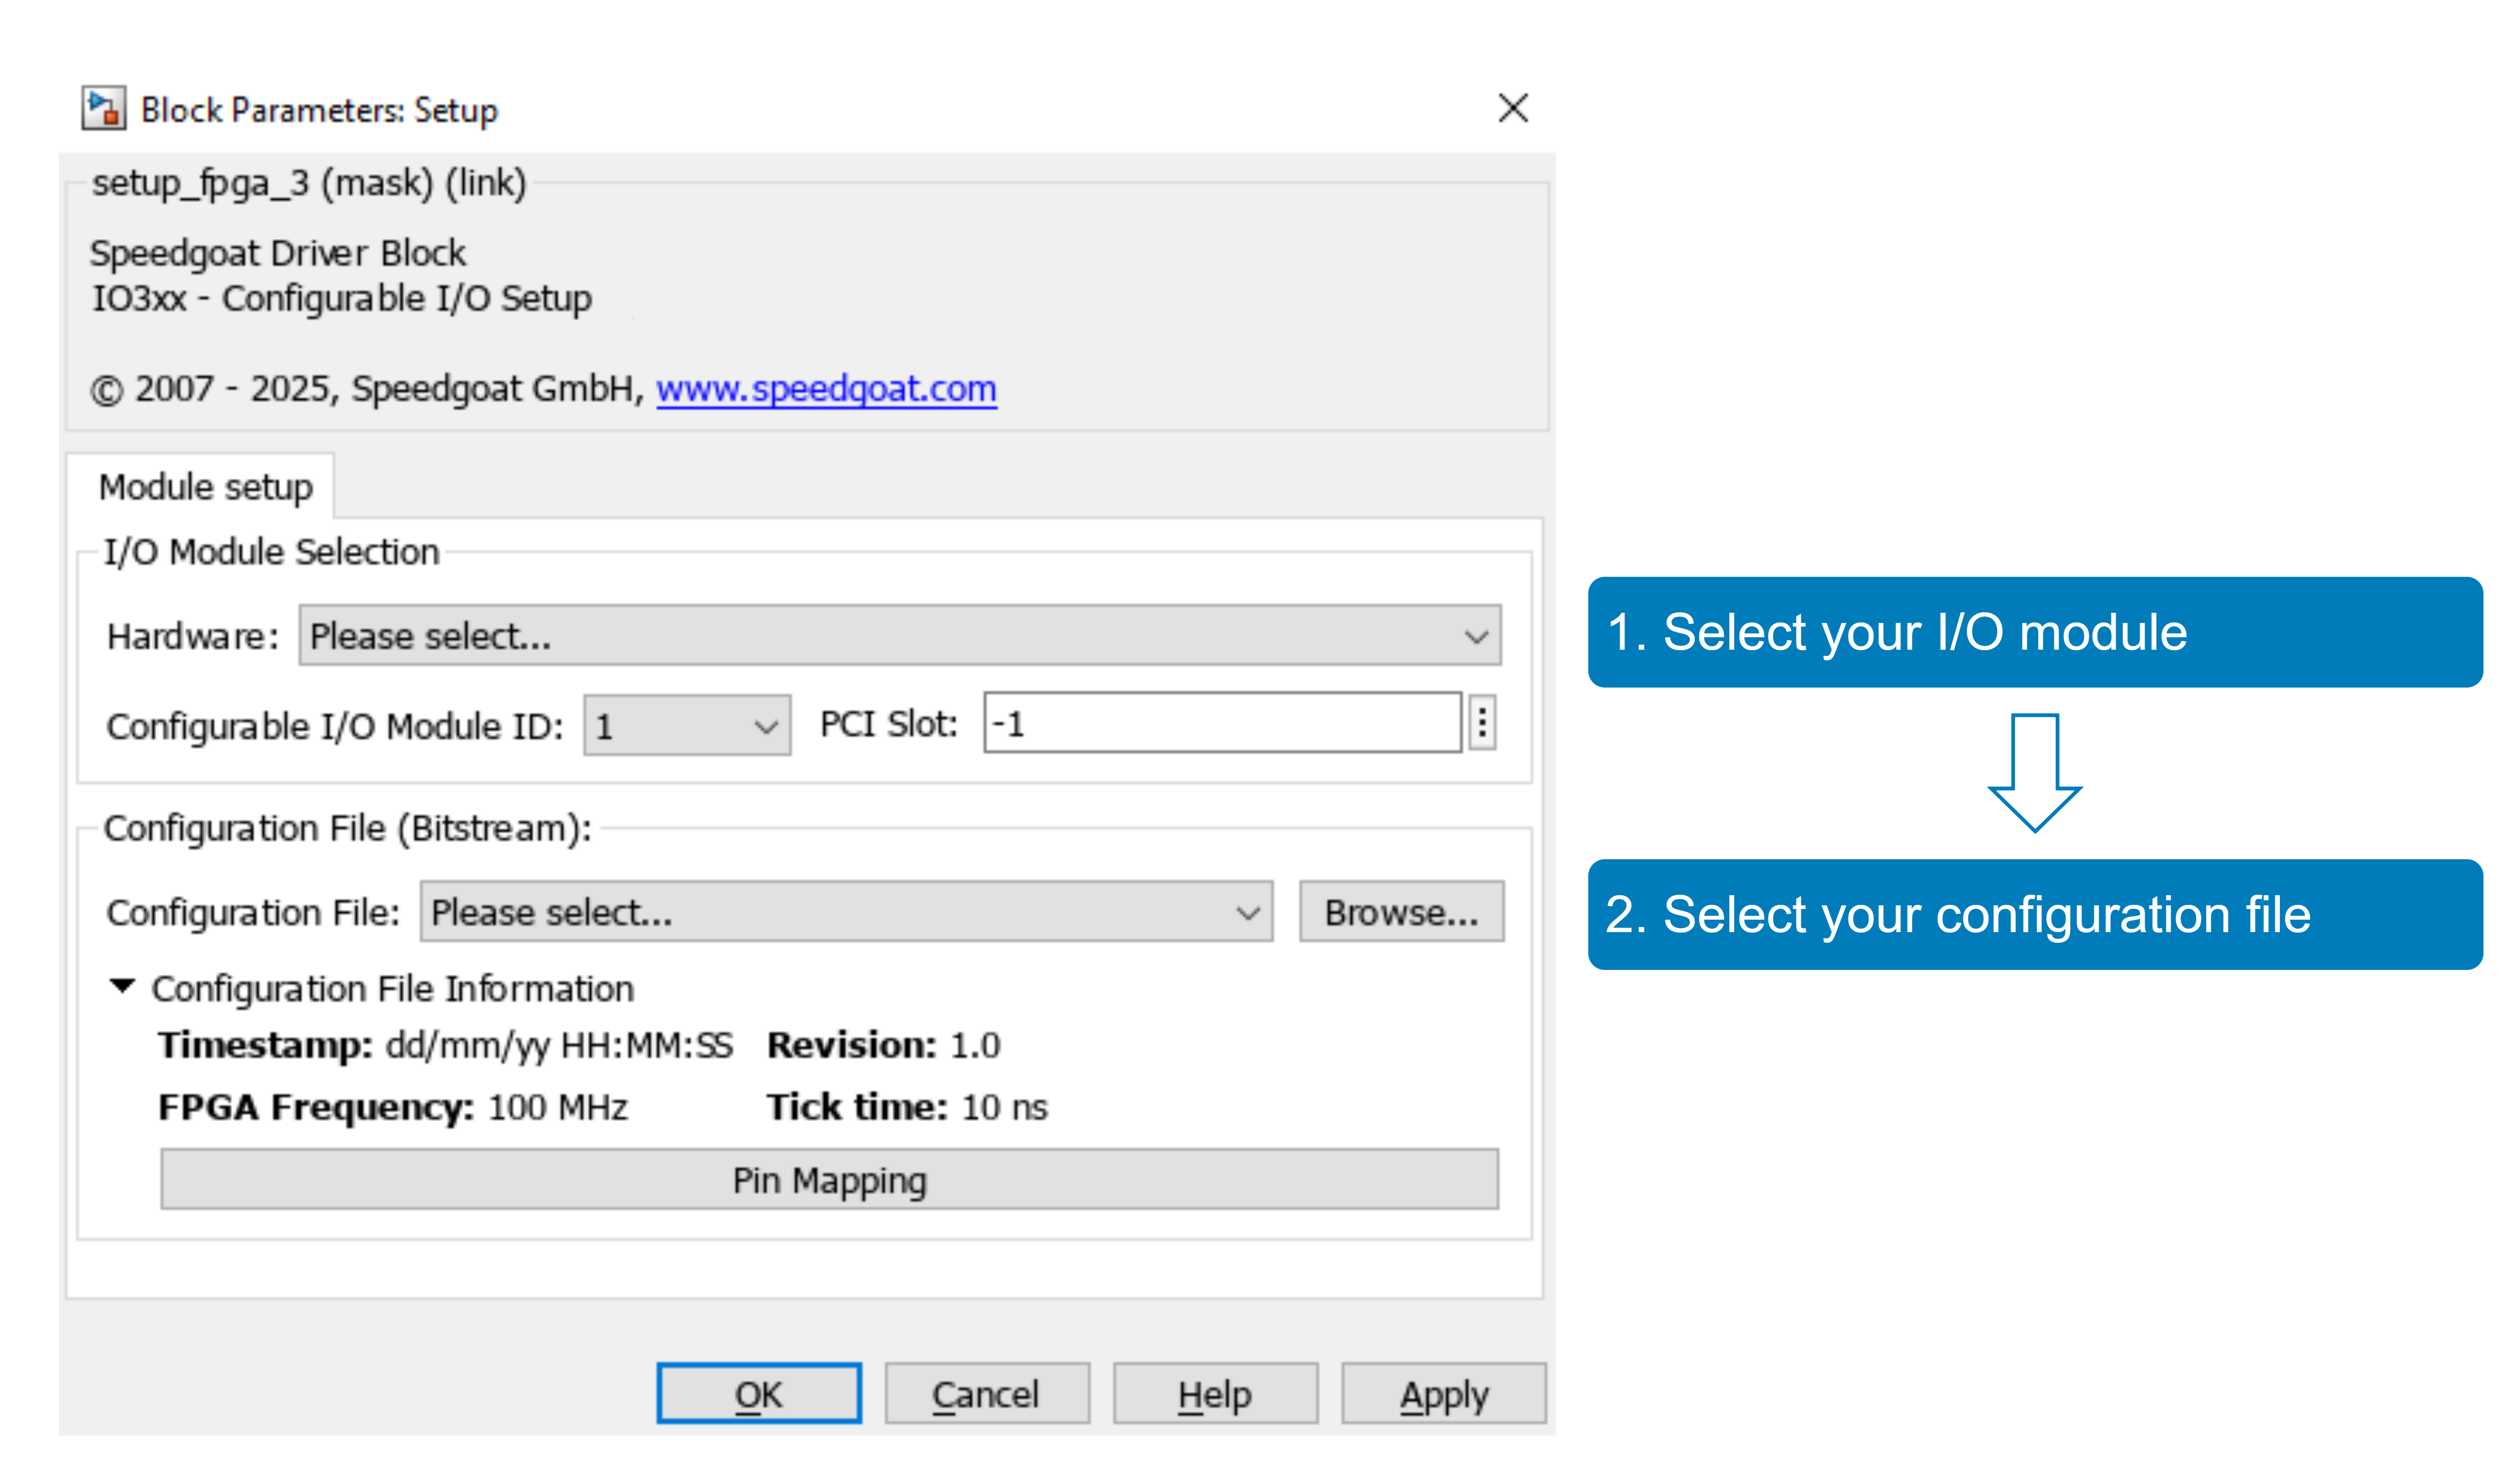

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

In the model, the I2C Master writes 4 data bytes to slave ID 24 and reads 4 data bytes from the same slave. The **Bitrate** parameter in the I2C Master read and I2C Master write blocks defines the I2C clock rate. It is implemented with a clockdivider and therefore can't achieve any arbitrary clockrate and is rounded towards the nearest achievable clockrate given by dividing the FPGA clockrate with an whole integer.  In this model the Bitrate is set to 100 kHz. This is an exactly achievable rate since the FPGA is running on a 75 MHz clock.

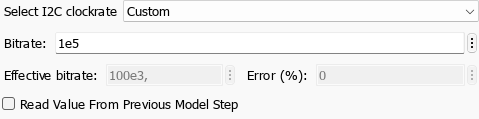

The Master first sends the slave address (in this example 24) to the slave, followed by a configuration byte to specify the slave register address. 

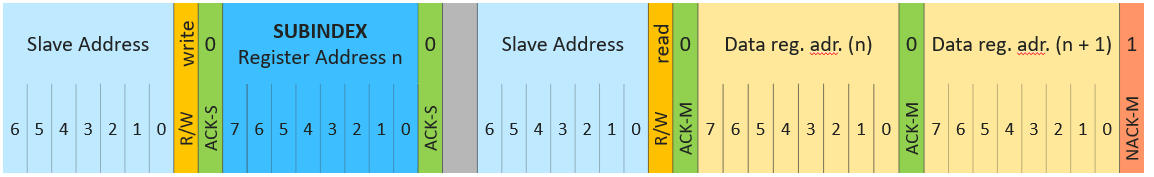

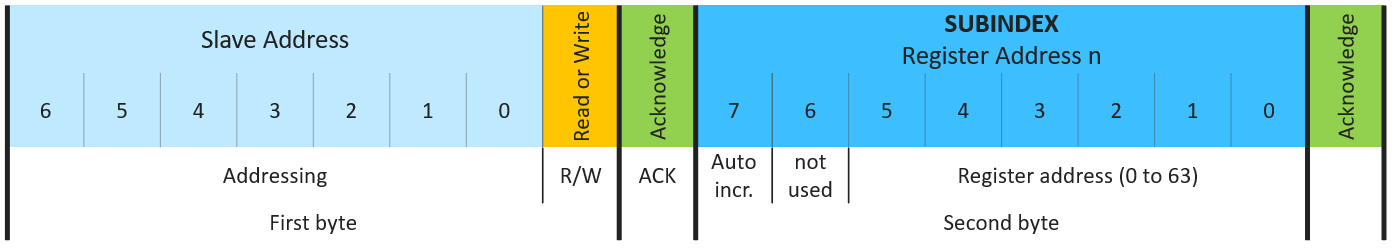

In the I2C Slave setup block, the **Skip Register Addressing **checkbox must be unchecked, so that the I2C Slave expects to receive a subindex byte prior to a write access on the registers.

The initial register address to write on is 2, defined in the I2CM_writeSubIndex constant. To read the 4 data bytes on the slave, the I2C Slave read block must configure the **Registers** [3,4,5,6]. In addition to the data output the read block has the data valid port enabled. This port indicates if the value on the data output was already read in a previous sample step or if it has been updated by the master since. The ouputs showing the last register written by the Master module such as the corresponding valid output are also enabled. The model is configured so, that the I2C Slave read block runs 3x faster that the I2C Master write block. Therfore the valid outputs only set to 1, every 3rd sample step.

The I2C Slave implements 2x 256 byte buffers. One buffer is used for reading and one for writing data to the Master. In the model, the I2C Slave write block writes 4 data bytes to registers 1 to 4 of the read buffer. These are then read by the Master with the I2C Master read block.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope **Scope I2CM read** and open the Simulink scope **Scope I2CS read**. They must display the following data:

**Scope I2CM read** 

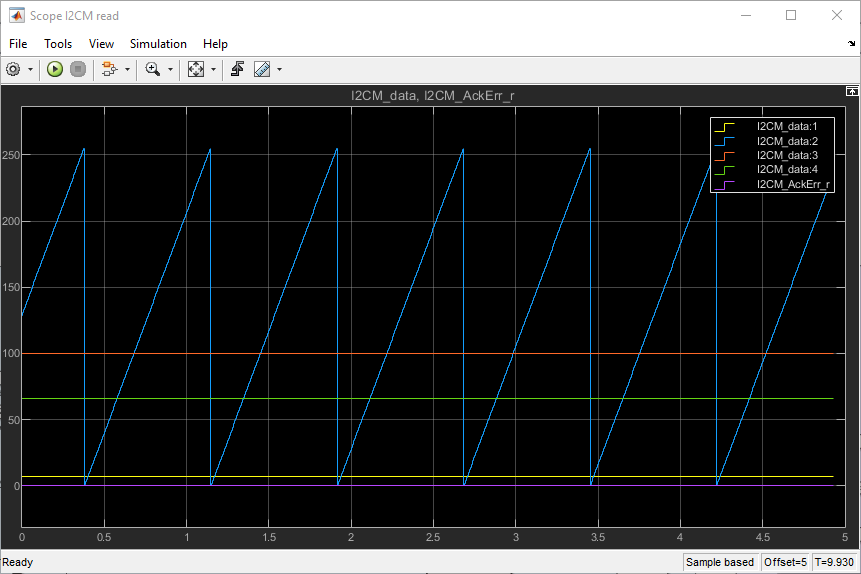

**Scope I2CS read**

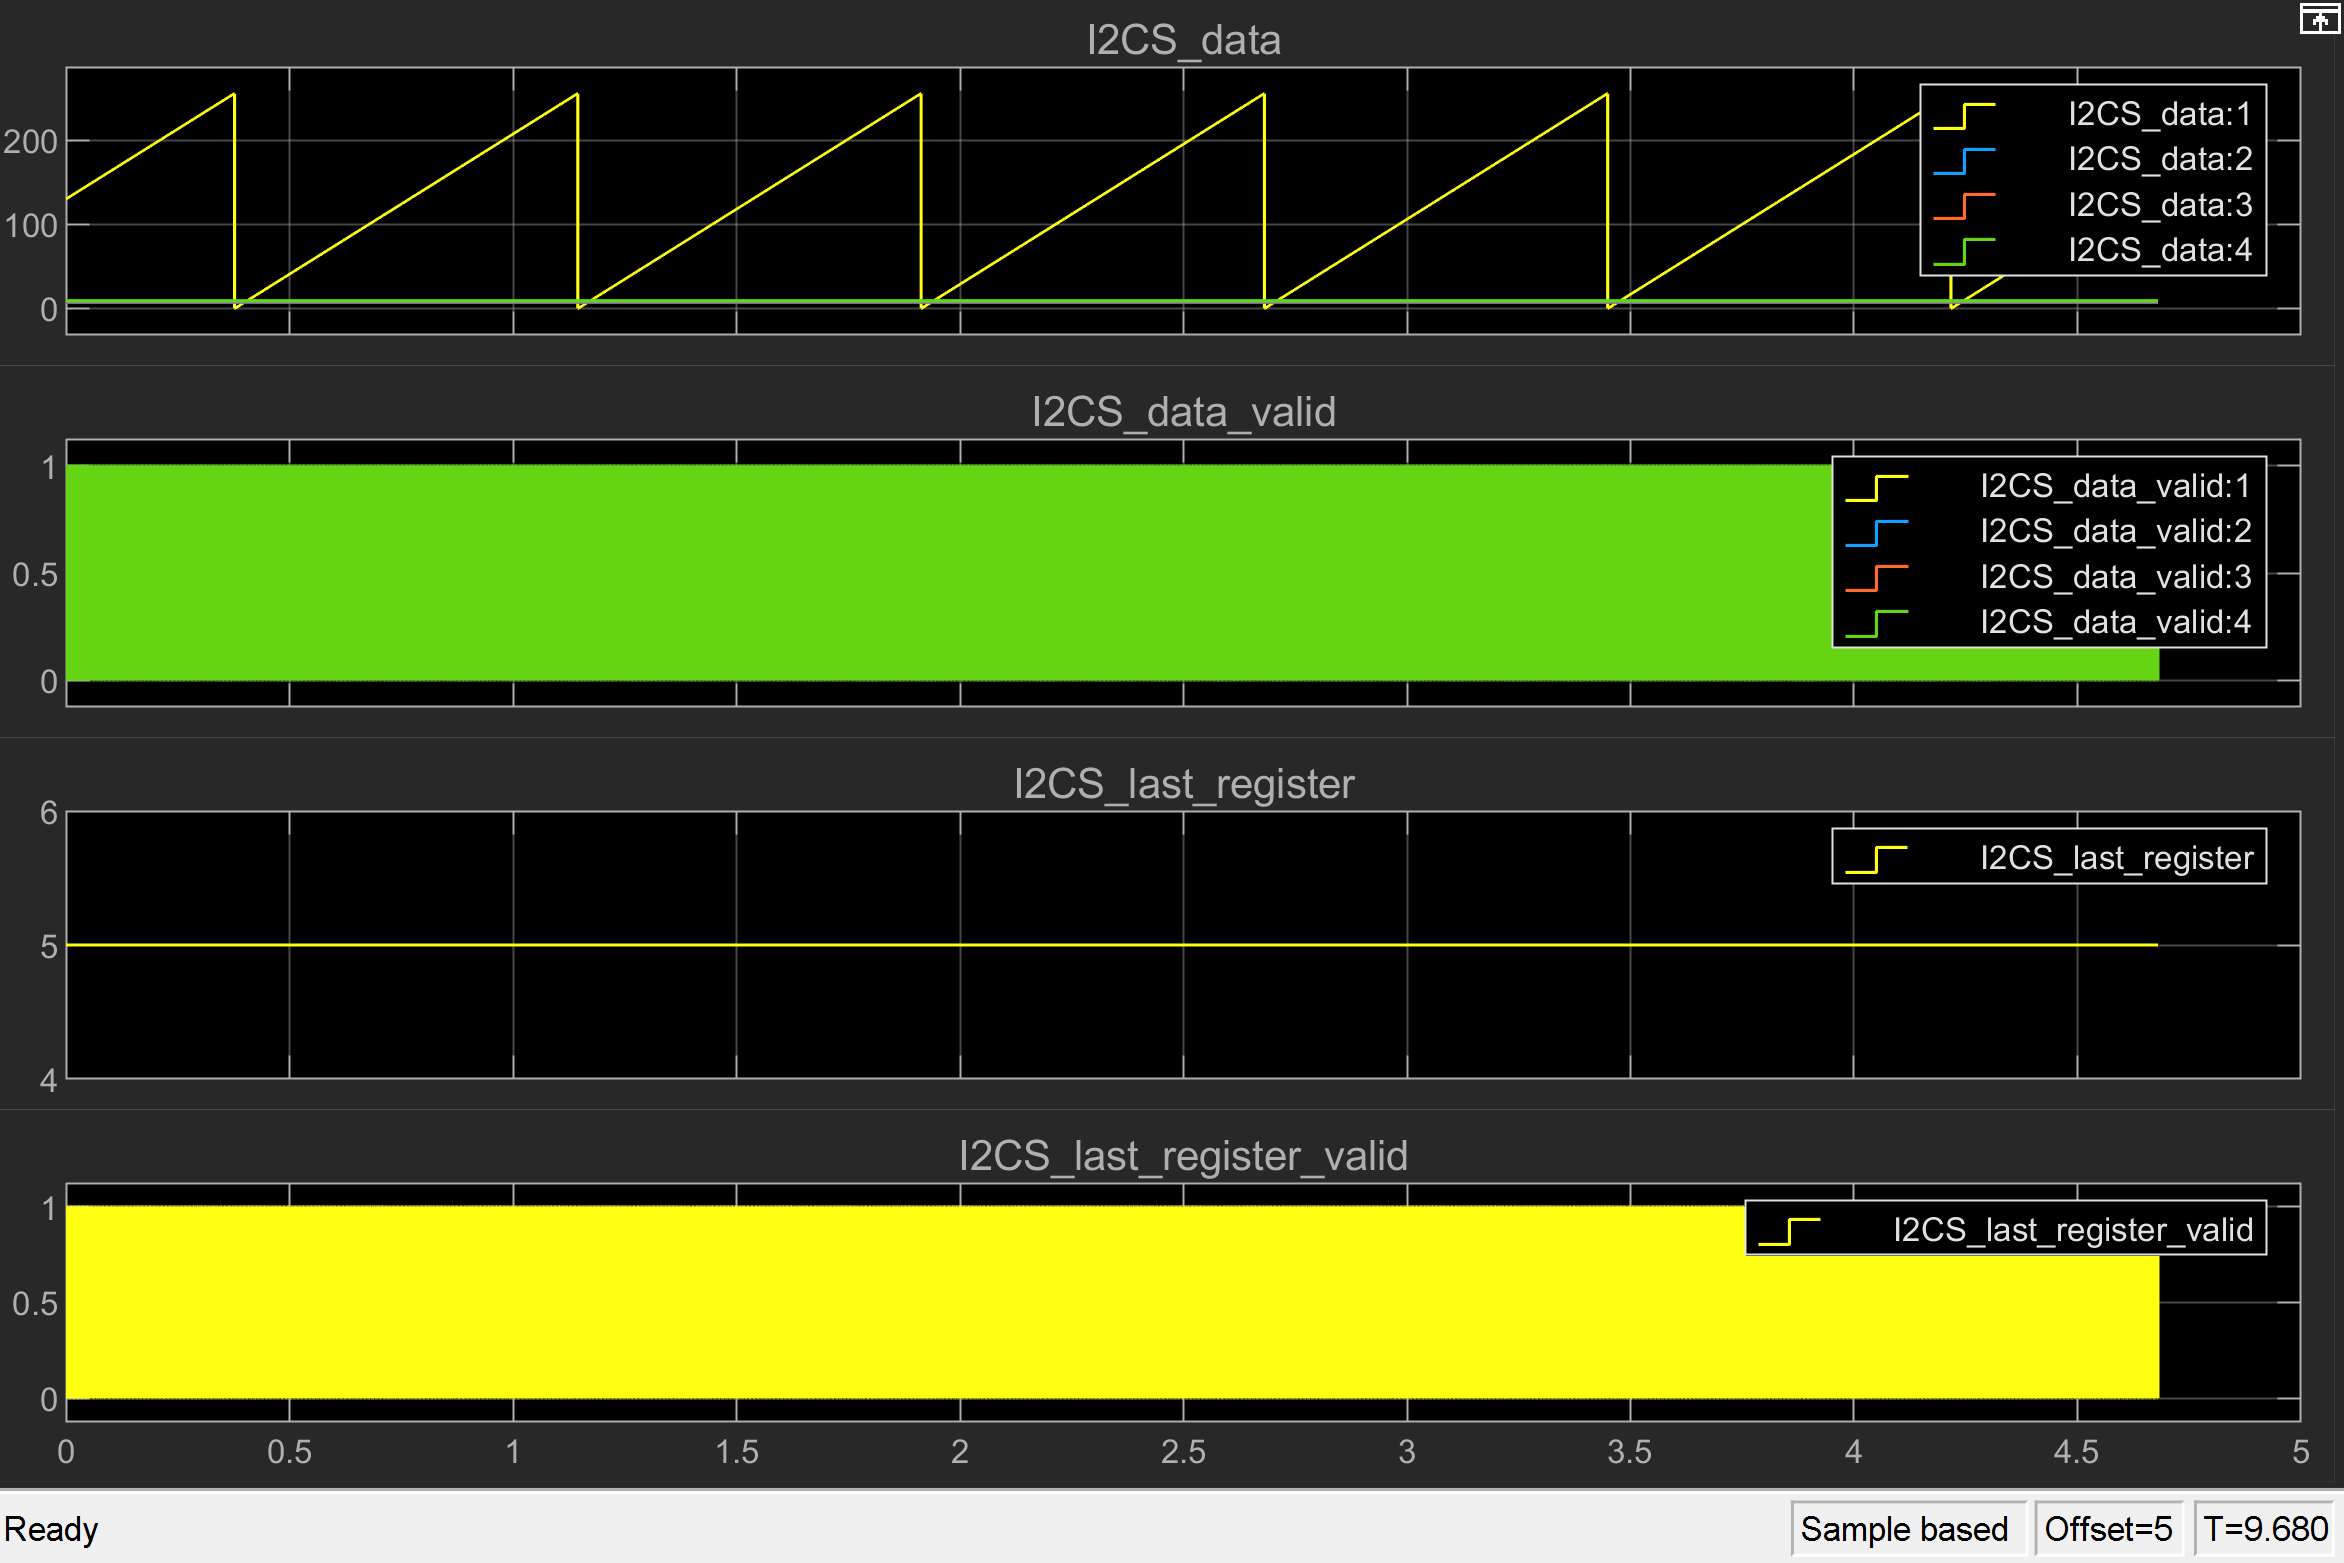

## Additional References

- [I2C documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_i2c)